Exploratory Group Assignment

1) Slide A: The codes for creating the "sine grate" images (images with  stripes) have been provided to you. Use either of those two codes and  plot images for 3 different frequencies of sine or cosine waves. Plot  the Fourier transforms of the 3 images. - 10 points

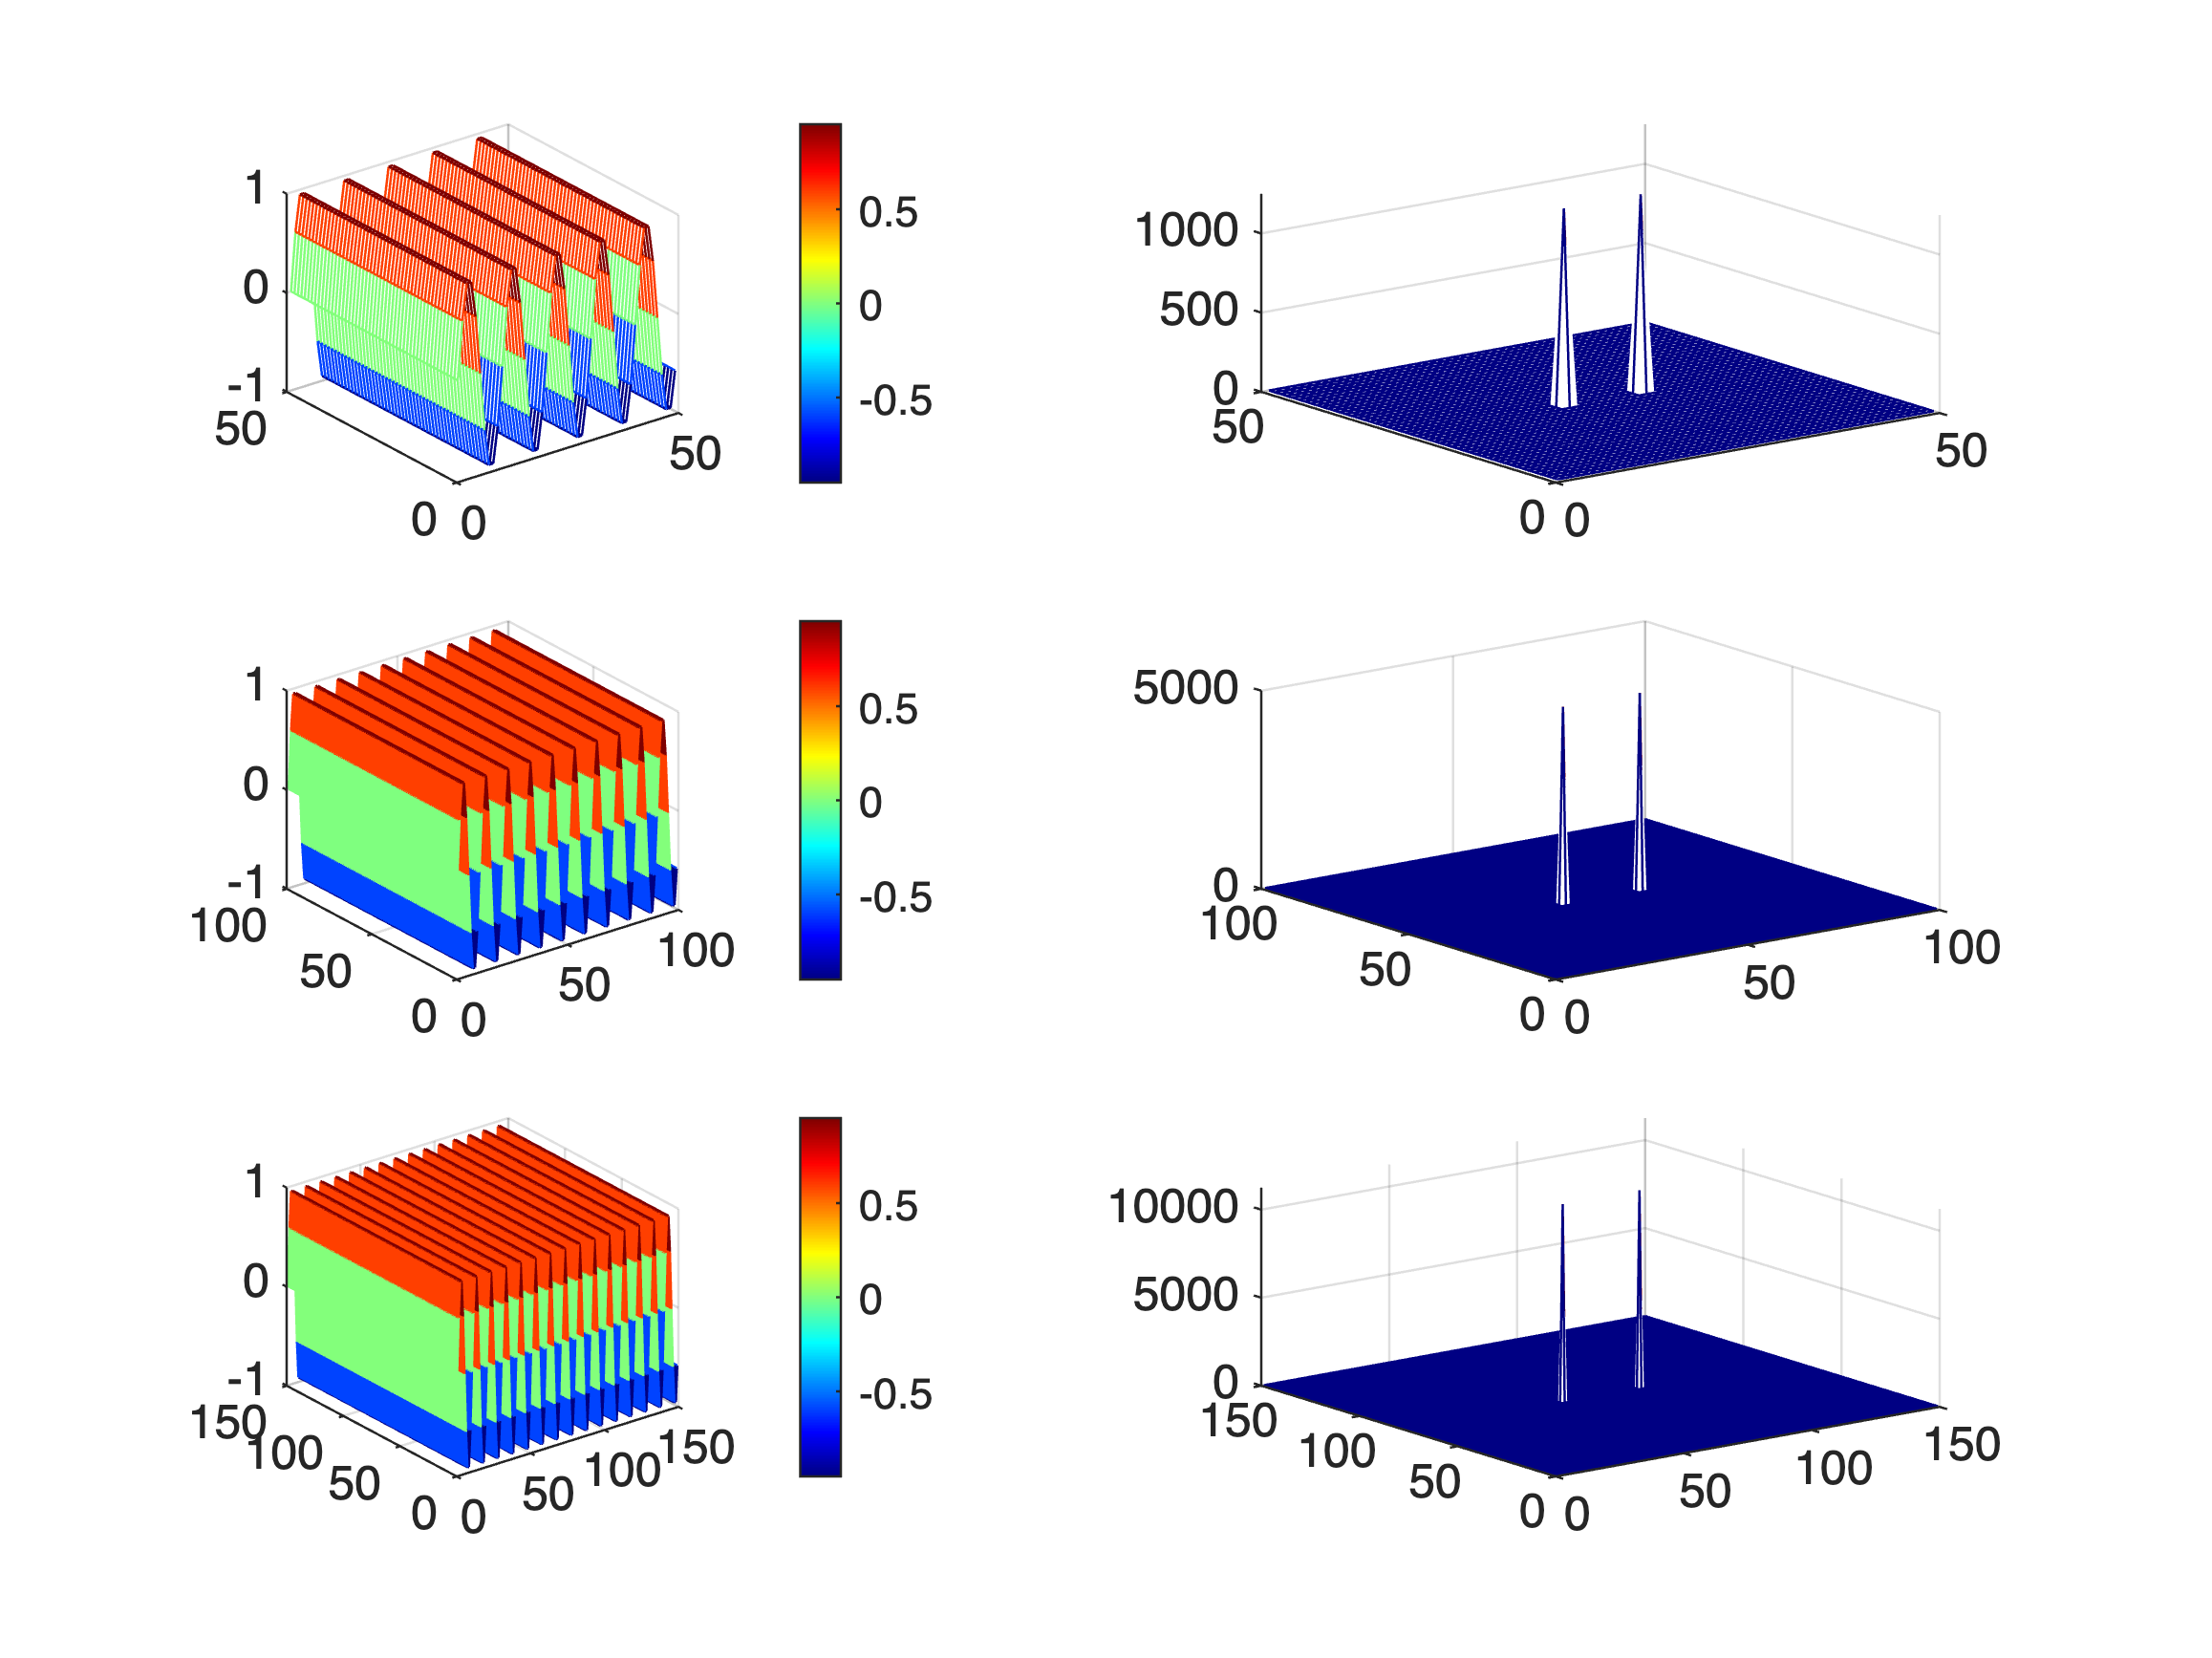

% from provided CG2DFT.m
N1 = 5; % Number of cycles in the sin wave
N2 = 10;
N3 = 15;
Step=0.1; % Resolution

NN1=N1/Step;
x1=sin(2*pi*[0:Step:N1-Step]);
xx1=zeros(NN1,NN1);
for i=1:NN1
xx1(i,:)=x1;
end

NN2=N2/Step;
x2=sin(2*pi*[0:Step:N2-Step]);
xx2=zeros(NN2,NN2);
for i=1:NN2
xx2(i,:)=x2;
end

NN3=N3/Step;
x3=sin(2*pi*[0:Step:N3-Step]);
xx3=zeros(NN3,NN3);
for i=1:NN3
xx3(i,:)=x3;
end

subplot(3,2,1)
XX1=fft2(xx1);
mesh(xx1);
colorbar;
subplot(3,2,2)
mesh(abs(fftshift(XX1)));

XX2=fft2(xx2);
subplot(3,2,3)
mesh(xx2);
colorbar;
subplot(3,2,4)
mesh(abs(fftshift(XX2)));

XX3=fft2(xx3);
subplot(3,2,5)
mesh(xx3);
colorbar;
subplot(3,2,6)
mesh(abs(fftshift(XX3)));

2) Slide B: Create these three shapes in MATLAB or Python, find their Fourier transforms, and verify whether the Fourier transforms shown on  the right are correct. - 10 points

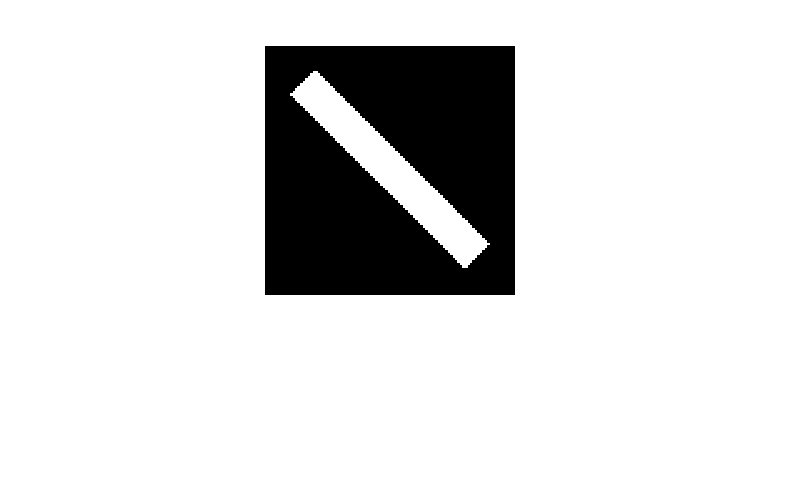

% rect = zeros(100,100);
% rect(30:50,20:80) = 1;
% % rect = imread('rect.png');
% figure;
% imshow(rect);

figure;
rect = poly2mask([10 20 90 80], [20 10 80 90], 100, 100);

imshow(rect)

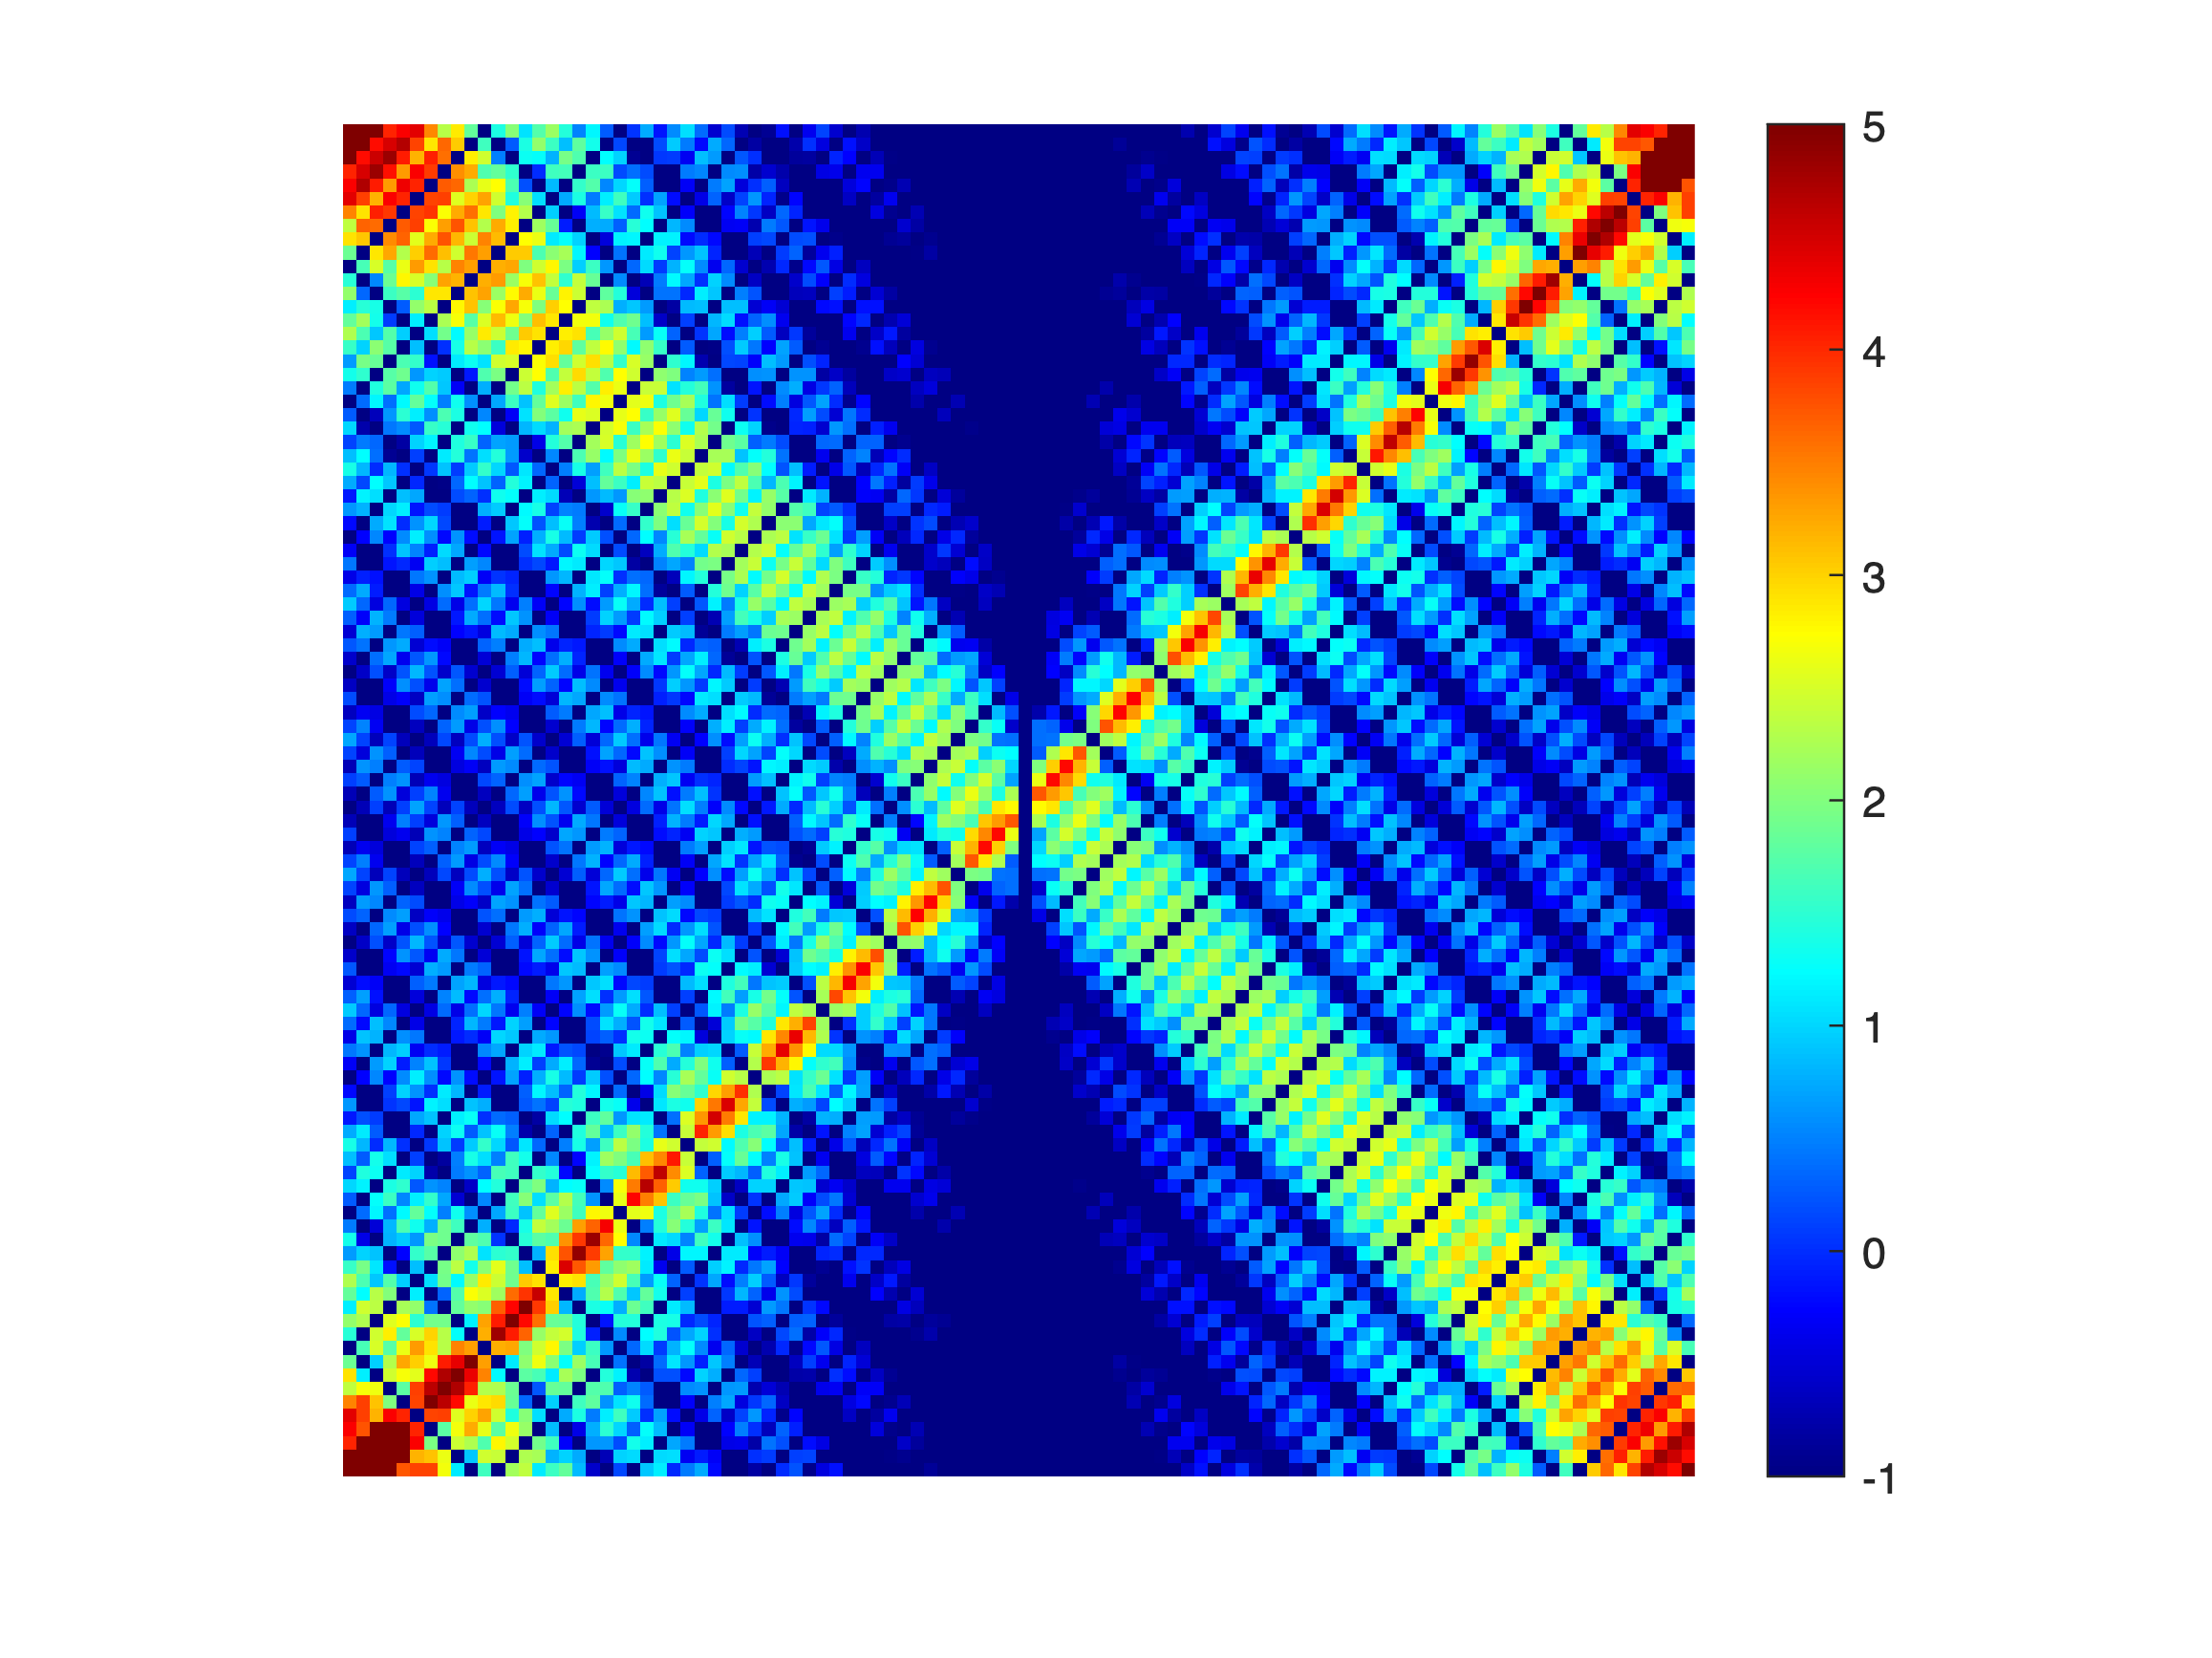


figure;
F = fft2(rect);
F2 = log(abs(F));
imshow(F2, [-1 5], "InitialMagnification","fit");
colormap(jet); colorbar

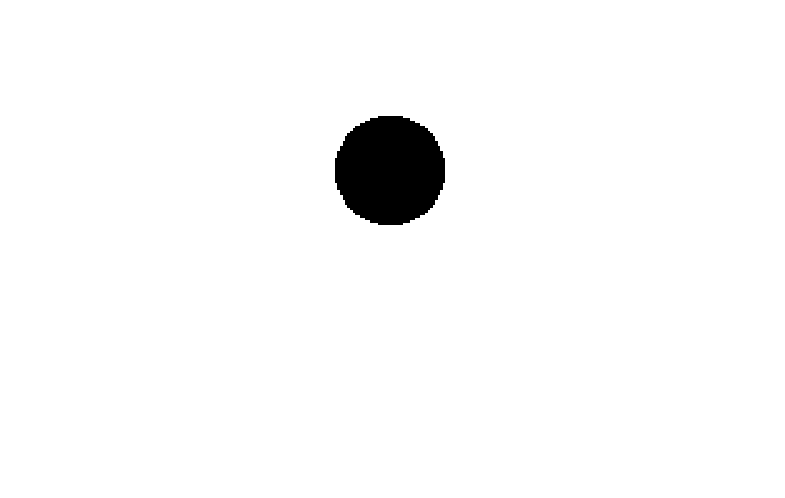

%%Make circle 
th = linspace(0,2*pi) ;
R = 5 ;  % Radius of circle 
C = [0 0] ; % Center of circle 
xc = C(1)+R*cos(th) ; yc = C(2)+R*sin(th) ;
%%Make mesh
N = 100 ;
x = C(1)+linspace(-R,R,N) ;
y = C(2)+linspace(-R,R,N) ;
[X,Y] = meshgrid(x,y) ;
Z = (X.^2+Y.^2) ;
%%Make matrix
iwant = zeros(size(Z)) ;
iwant(Z<=R) = 1 ;
iwant = imcomplement(iwant);

figure
imshow(iwant)

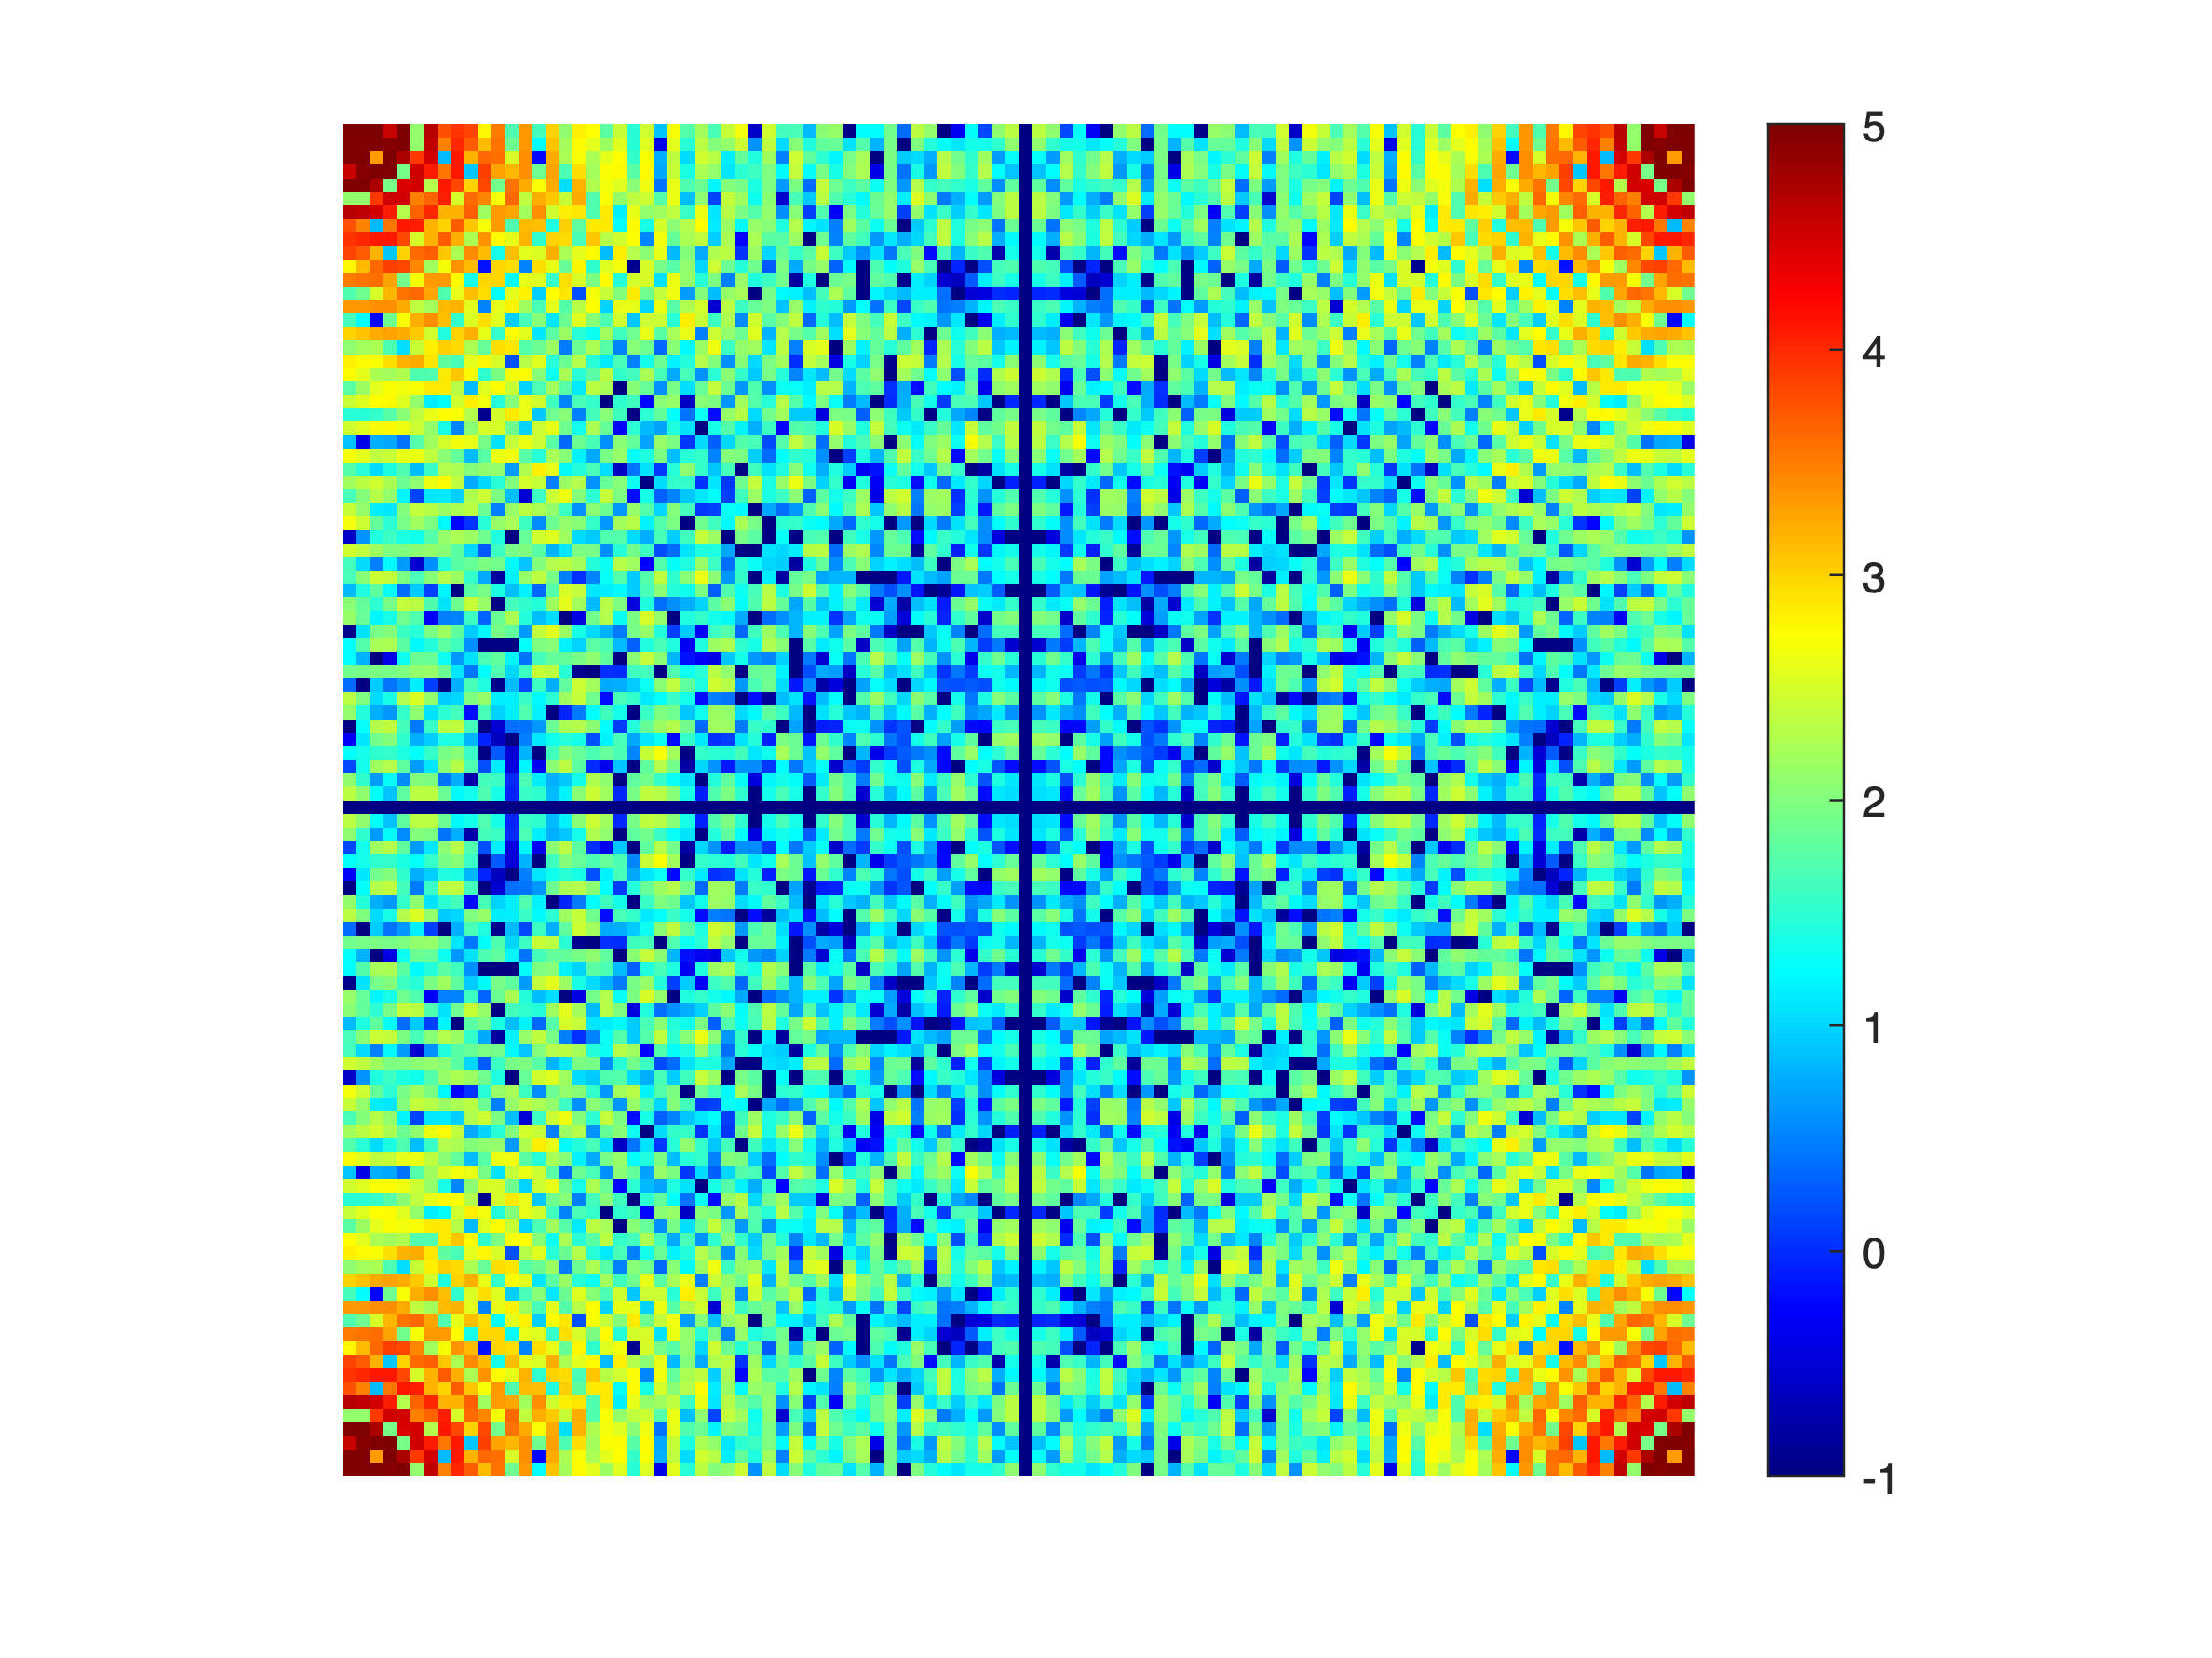



figure;
F3 = fft2(iwant);
F4 = log(abs(F3));
imshow(F4, [-1 5], "InitialMagnification","fit");
colormap(jet); colorbar

ex = zeros(200,200)

ex =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

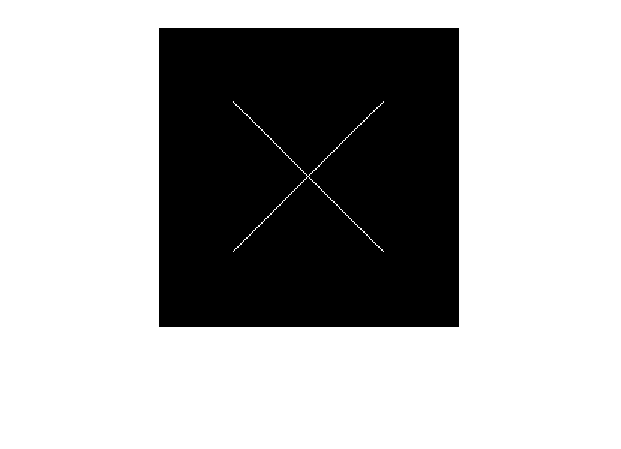


for exx = 50:150
    for eyy = 50:150
        if abs(exx-100) == abs(eyy-100)
            ex(exx,eyy) = 1;
        end
    end
end

figure
imshow(ex)


figure;
F5 = fft2(ex);
F6 = log(abs(fftshift(F5)));
figure
imshow(F5, [-1 5], "InitialMagnification","fit");

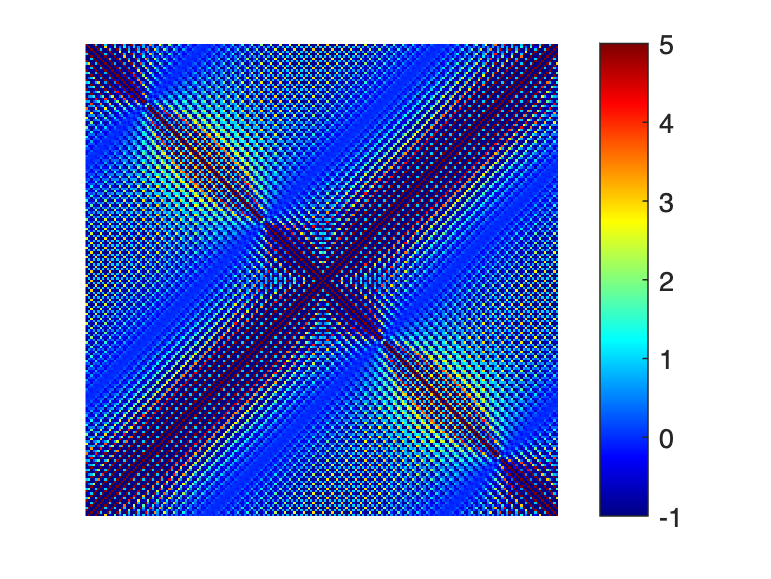

colormap(jet); colorbar

3) Use an image of your choice, plot its Fourier transform. Comment  on whether interpreting the Fourier Transform was intuitive. - 10  points. 

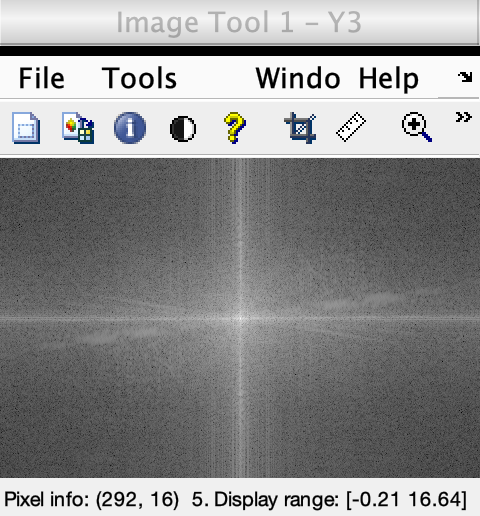

I = imread("../images/IMAGE004.jpg");

Ig = im2gray(I);
Y = fft2(Ig);

Y1 = abs(Y);

Y2 = log(abs(Y));

Y3 = log(abs(fftshift(Y)));

% imtool(Y1,[]);
% imtool(Y2,[]);
imtool(Y3,[]);

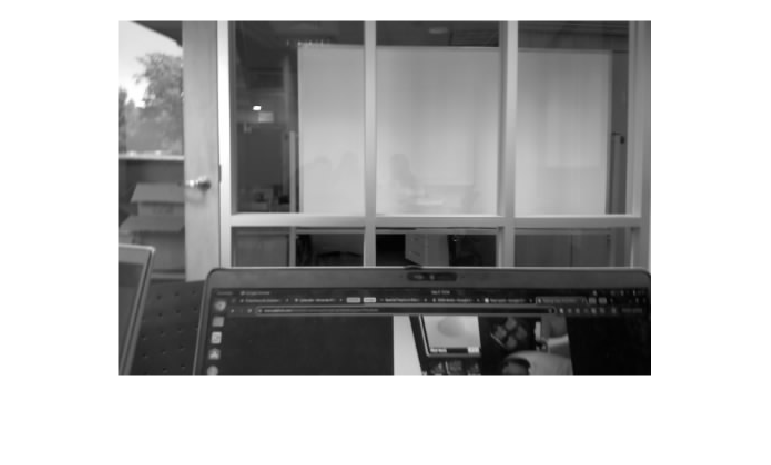

figure;
imshow(Ig);